# **Расчет времени распространения в пространстве сигнала**

**Возможная длина импульса**

clear all 
clc
fs=1e11; % Частота дискретизации %%%%%% !!!!!!!!!!!!!
T=1/fs % период дискретизации

T = 1.0000e-11

K=5e5; % количество отсчетов с антенны %%%%%% !!!!!!!!!!!!!
PerIssledovaniya = K * T

PerIssledovaniya = 5.0000e-06

t = (0:K-1)*T;
R = 20000;% (м) расстояние от антенны до цели
h = 30; % (м) высота антенны 
H1 = 400; % (м) высота цели 
c = 3e8;
H2 = H1 - h;
H3 = H1 + h;
BA = hypot(R,H2);
CA = hypot(R,H3);
raznost_M = CA - BA % (м) разность прихода сигналов 

raznost_M = 1.1998

raznost_S = raznost_M/c% (c) разность прихода сигналов 

raznost_S = 3.9992e-09

Os4et_zaderzhki = round(raznost_S/T); % количество отсчетов задержки 
max_Tsig6 = 12000/c

max_Tsig6 = 4.0000e-05

PeriodIzl = max_Tsig6/10 % (c) В 3 раз меньше допустимого длительность импульса

PeriodIzl = 4.0000e-06

Os4et_perIzl = round(PeriodIzl/T);
protsentNeperecritiya = raznost_S/PeriodIzl*100 

protsentNeperecritiya = 0.1000


alfa = asin(H2/BA+H3/CA);
UgolPrihoda = rad2deg(alfa)

UgolPrihoda = 2.2920


Fnes = 10e9;
deviatsia = 15e6;
FreqMax = Fnes+deviatsia;
FreqMin = Fnes-deviatsia;

# **Вводные данные по нарпавлениям**

th1 = 0; % направление #1
th2 = UgolPrihoda; % направление #2 
% Vkm=[400  400]; %км/ч скорость цели с направления D
% Vm=Vkm/3.6; %м/с
% Fd1=(2*Vm)/0.03 % частота Доплера  с направления D 
p1=1; % мощность сигнала с направления #1
p2=1; %мощность сигнала с направления #2
d=0.5; % расстояния между элементов относительно lambda
M=200; % количество элементов антенны
doas=[th1 th2]*pi/180; %DOA s of signals in rad.
P=[p1 p2];
F=[Fnes Fnes];

NP=1; % мощность шума
r=length(doas);
%%%% Вектора прихода от различных источников %%%%%%%%%%%
for m=1:M
    parfor th=1:r
        A(m,th)=exp(+1i*2*pi*(m-1)*d*sin(doas(th)));
    end
end

# Signal generation

## Рост ЛЧМ (Linear Chirp) 

% y = chirp(t,FreqMin,PeriodIzl,FreqMax);
% signal = [y(1,1:Os4et_perIzl),zeros(1,K-Os4et_perIzl)]
% a = chirp(t,FreqMin,PeriodIzl/2,FreqMax);
% b = chirp(t,FreqMin,PeriodIzl/2,FreqMax);
% signal = [a(1,1:Os4et_perIzl/2),rot90(b(1,1:Os4et_perIzl/2),2),zeros(1,K-Os4et_perIzl)]

## Сигнал зерканый ЛЧМ (2крышы)

% a = chirp(t,FreqMin,PeriodIzl/2,FreqMax);
% b = chirp(t,FreqMin,PeriodIzl/2,FreqMax);
% signal = [a(1,1:Os4et_perIzl/4),rot90(b(1,1:Os4et_perIzl/4),2),a(1,1:Os4et_perIzl/4),rot90(b(1,1:Os4et_perIzl/4),2),zeros(1,K-Os4et_perIzl)]

6oy

% a = chirp(t,FreqMin,PeriodIzl/2,FreqMax);
% b = chirp(t,FreqMin,PeriodIzl/2,FreqMax);
% signal = [rot90(b(1,1:Os4et_perIzl/4),2),a(1,1:Os4et_perIzl/4),rot90(b(1,1:Os4et_perIzl/4),2),a(1,1:Os4et_perIzl/4),zeros(1,K-Os4et_perIzl)]

Сигнал зерканый ЛЧМ (8)

a = chirp(t,FreqMin,PeriodIzl/2,FreqMax);
b = chirp(t,FreqMin,PeriodIzl/2,FreqMax);
signal = [rot90(b(1,1:Os4et_perIzl/8),2),a(1,1:Os4et_perIzl/8),rot90(b(1,1:Os4et_perIzl/8),2),a(1,1:Os4et_perIzl/8),rot90(b(1,1:Os4et_perIzl/8),2),a(1,1:Os4et_perIzl/8),rot90(b(1,1:Os4et_perIzl/8),2),a(1,1:Os4et_perIzl/8),zeros(1,K-Os4et_perIzl)]

signal =    -0.1569    0.4532    0.8904    0.9880    0.7088    0.1592   -0.4510   -0.8893   -0.9883   -0.7104   -0.1616    0.4489    0.8882    0.9887    0.7121    0.1639   -0.4468   -0.8871   -0.9890   -0.7137   -0.1662    0.4447    0.8860    0.9894    0.7154    0.1685   -0.4426   -0.8849   -0.9897   -0.7170   -0.1709    0.4405    0.8838    0.9901    0.7187    0.1732   -0.4384   -0.8827   -0.9904   -0.7203   -0.1755    0.4363    0.8816    0.9907    0.7219    0.1778   -0.4341   -0.8805   -0.9910   -0.7236


## Сигнал зерканый ЛЧМ (7)

% a = chirp(t,FreqMin,PeriodIzl/2,FreqMax);
% b = chirp(t,FreqMin,PeriodIzl/2,FreqMax);
% signal = [a(1,1:Os4et_perIzl/8),rot90(b(1,1:Os4et_perIzl/8),2),a(1,1:Os4et_perIzl/8),rot90(b(1,1:Os4et_perIzl/8),2),a(1,1:Os4et_perIzl/8),rot90(b(1,1:Os4et_perIzl/8),2),a(1,1:Os4et_perIzl/8),rot90(b(1,1:Os4et_perIzl/8),2),zeros(1,K-Os4et_perIzl)]
% %%%%%%генерация шума (АБГШ)%%%%%%%%%
noise=wgn(M,K,NP,'real','linear') %некоррелированный шум

noise =     0.1635   -0.6612   -0.9056    0.9323    1.0910   -1.4180   -0.3192   -0.9179    1.3803   -0.5676    0.2742    1.5699   -0.0013    0.0291    0.0313    0.4850   -1.3385   -0.9914   -1.0408   -0.2855   -0.9861   -0.9997    0.7164   -1.2828   -1.1641   -1.3468    0.4979    0.1132   -1.8082   -0.3363   -0.0454   -0.4087   -0.4481    0.6530   -1.4069    0.0498   -0.5782    1.1298   -1.3869   -1.5317   -0.8518   -0.0468    1.1400    0.3674    1.3709    0.6347    1.1250   -1.0464   -1.2532   -0.5633
   -0.6924   -0.3438   -0.8718   -1.2503    0.3278   -0.5887    1.3522   -0.3931    0.1061   -0.8188   -0.1891    0.0907   -0.3118    0.7063    0.2985   -0.1910    1.9099   -0.0526   -0.7852   -0.6361   -0.9234    0.5381    1.4690    0.2624   -0.3515    0.0379    0.7920    0.9046    1.0980    2.8306    0.1876    0.8837    1.3076    0.7199   -1.5622    0.1935   -0.8165    1.1592    0.8856    1.0185   -0.8224   -3.4707   -1.2574    0.4341    0.2499   -0.0023    0.2415    1.8899   -1.9916 

A;
diag(sqrt(P));
signal;

# Time Delay

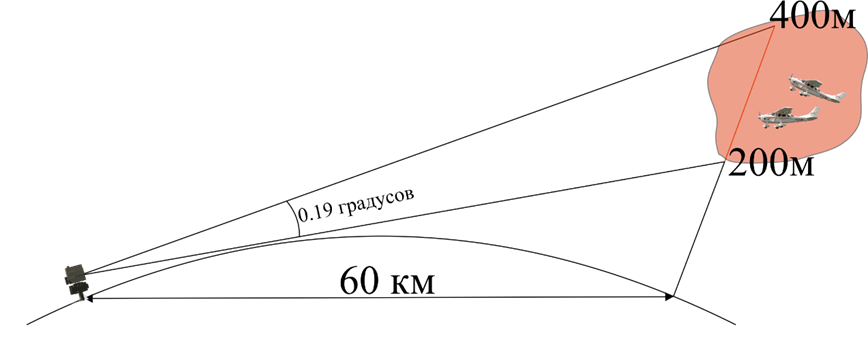

signal2=[zeros(1,Os4et_zaderzhki),signal(1,1:K-Os4et_zaderzhki)]; %  #1 цель
sig1=[signal; signal2] % сигнал с задержками

sig1 =    -0.1569    0.4532    0.8904    0.9880    0.7088    0.1592   -0.4510   -0.8893   -0.9883   -0.7104   -0.1616    0.4489    0.8882    0.9887    0.7121    0.1639   -0.4468   -0.8871   -0.9890   -0.7137   -0.1662    0.4447    0.8860    0.9894    0.7154    0.1685   -0.4426   -0.8849   -0.9897   -0.7170   -0.1709    0.4405    0.8838    0.9901    0.7187    0.1732   -0.4384   -0.8827   -0.9904   -0.7203   -0.1755    0.4363    0.8816    0.9907    0.7219    0.1778   -0.4341   -0.8805   -0.9910   -0.7236
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

X=A*diag(sqrt(P))*sig1+noise; %генерация сигнала в решетке
R=X*X'/K; %Spatial correlation matrix
R;
[E ,D]=eig(R); %разложение корреляционной матрицы на собственные вектора и значения 
E; %собственные вектора
D; %собственные значения
[D,I]=sort(diag(D),1,'descend'); %Поиск r наибольших собственный значений
r = 2

r = 2

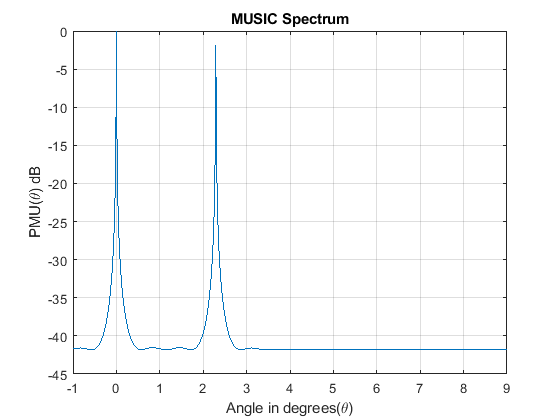

E=E (:,I); %сортировка, что сигнальные значения стояли сначала
Es=E (:,1:r); %получения матрицы сигнального подпространства
En=E(:,r+1:M); %получения матрицы шумового подпространства

%%%%%%%%%%%%%% MUSIC algorithm %%%%%%%%%%%%%%
angles=(-1:0.01:9);
for m=1:M
    for th=1:length(angles)
        a(m,th)=exp(+1i*2*pi*(m-1)*d*sin(angles(th)*pi/180));
    end
end
for k=1:length(angles)
    %расчет MUSIC "spectrum" всевдоспектр
    music_spectrum(k)=(a(:,k)'*a(:,k))/(a(:,k)'*En*En'*a(:,k));
end


%%%%%%построение спектральной плотности мощности %%%%%%%%%%%%%%
music_spectrum=10*log10(abs(music_spectrum/max(music_spectrum)));

plot(angles,music_spectrum);
grid on
title('MUSIC Spectrum')
xlabel('Angle in degrees(\theta)')
ylabel('PMU(\theta) dB')

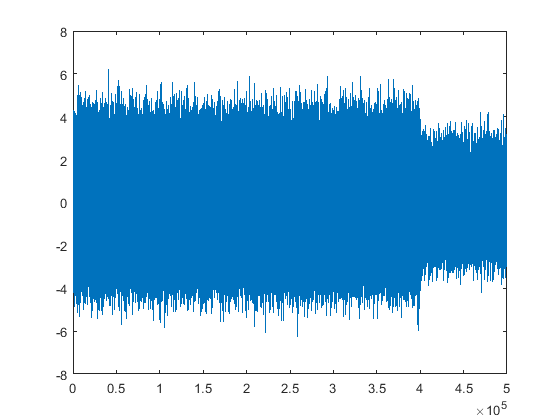

plot(X(1,:))